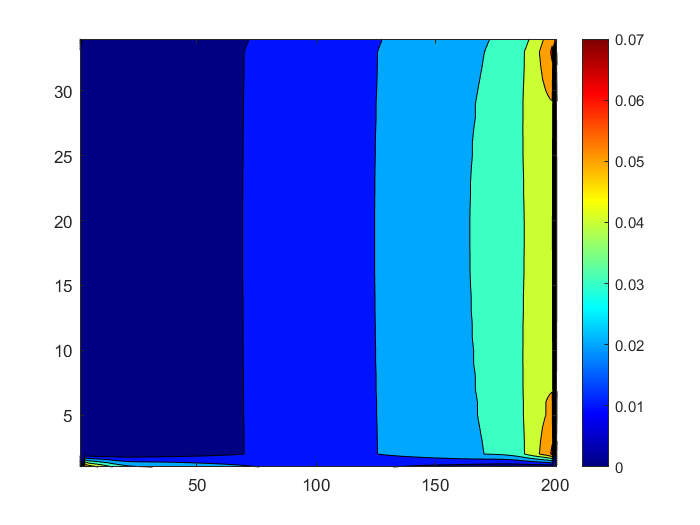

newData = readmatrix("2d_structured_200x20_016ms.csv");
newData = rmmissing(newData);
checker = newData(:,3)>0;
Data2 = newData(checker,:);
x2 = Data2(:,1);
y2= Data2(:,2);
p2 = Data2(:,4);
u2 = Data2(:,5);
v2 = Data2(:,7);
[~,i2y,~] = unique(round(y2,4));
[~,i2x,~] = unique(round(x2,4));
Pmap = NaN(size(i2x,1),size(i2y,1),5);
for n = 1:34
        g = round(y2,4) == round(y2((i2y(n))),4);
        if sum(g)<201
            g = round(y2,3) == round(y2((i2y(n))),3);
            if sum(g)<201
                g = round(y2,2) == round(y2((i2y(n))),2);
            end
        end
        Pmap(1:sum(g),n,1) = p2(g);
        Pmap(1:sum(g),n,2) = u2(g);
        Pmap(1:sum(g),n,3) = v2(g);
        Pmap(1:sum(g),n,4) = x2(g);
        Pmap(1:sum(g),n,5) = y2(g);
end
Pmap;
contourf(Pmap(:,:,1)')
colormap jet
colorbar

% contourf(Pmap(:,:,2)')
% colormap jet
% colorbar
% contourf(Pmap(:,:,3)')
% colormap jet
% colorbar
clear

newData = readmatrix("2d_structured_200x20_016ms.csv");
newData = rmmissing(newData);
checker = newData(:,3)<0;
Data2 = newData(checker,:);
x2 = Data2(:,1);
y2= Data2(:,2);
p2 = Data2(:,4);
u2 = Data2(:,5);
v2 = Data2(:,7);
[y2r,i2y,yi] = unique(round(y2,4));
[x2r,i2x,xi] = unique(round(x2,4));
Pmap = NaN(size(i2x,1),size(i2y,1),3);
for n = 1:34
        g = round(y2,4) == round(y2((i2y(n))),4);
        if sum(g)<201
            g = round(y2,3) == round(y2((i2y(n))),3);
            if sum(g)<201
                g = round(y2,2) == round(y2((i2y(n))),2);
            end
        end
        Pmap(1:sum(g),n,1) = p2(g);
        Pmap(1:sum(g),n,2) = u2(g);
        Pmap(1:sum(g),n,3) = v2(g);
        Pmap(1:sum(g),n,4) = x2(g);
        Pmap(1:sum(g),n,5) = y2(g);
end
Pmap;
contourf(Pmap(:,:,1)')
colormap jet
colorbar

% contourf(Pmap(:,:,2)')
% colormap jet
% colorbar
% contourf(Pmap(:,:,3)')
% colormap jet
% colorbar
clear